# **IO3xx Dshot - Loopback **

This example demonstrates the use of the Dshot v1 Tx and Rx driver blocks. The model is set up for a loopback configuration. Dshot pulses are emitted from two Tx Generation v1 channels. The signals are looped back on the terminal board to be detected by the Dshot Rx driver block. 

## Setup

### Prerequisites

You require the following to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- A Speedgoat configuration file that supports **1x Dshot RX channel and 1x Dshot Tx channel**  

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, Dshot pulses are emitted from the Dshot Tx and captured by the Dshot Rx channel. You must therefore connect the corresponding pins on the terminal board as indicated in the following pin wiring table. The exact pins depend on your specific configuration file (bitstream). 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Dshot_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

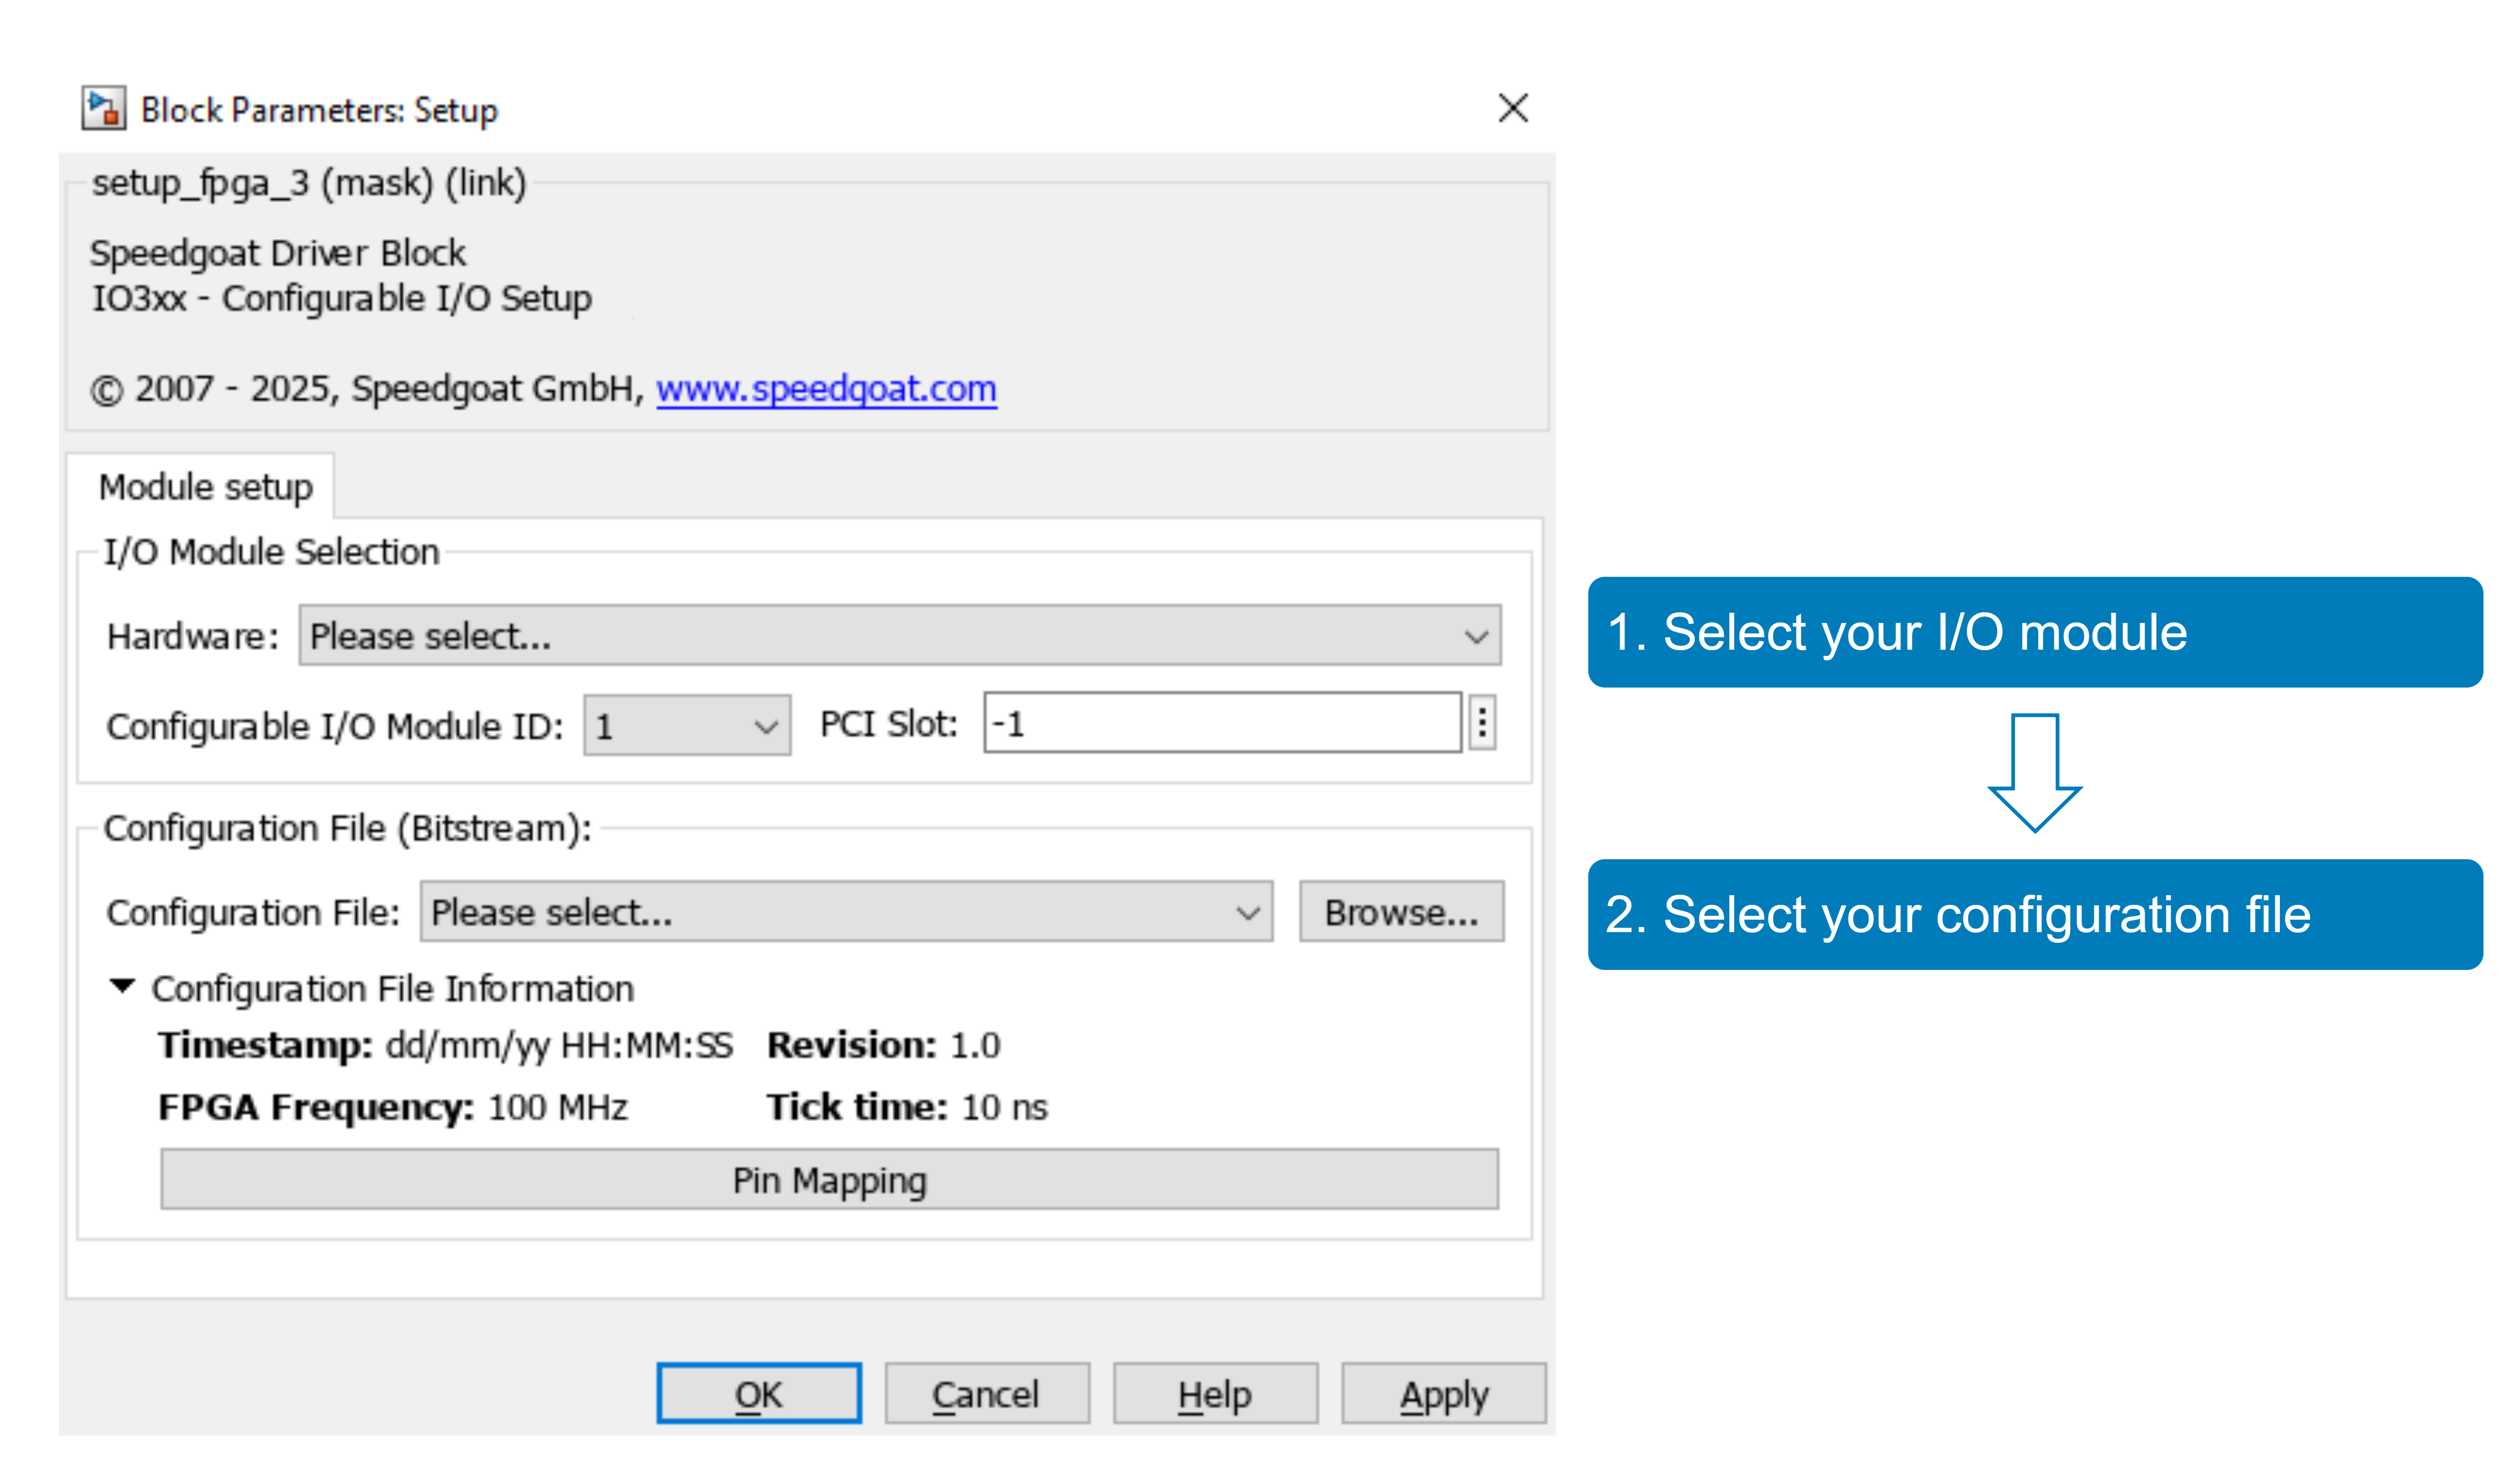

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description 

The model contains an instance of the Dshot Tx block and an instance of the Dshot Rx block. Both instances use channel 1 (**Channel Vector** parameter). The values of an 11-bit counter are transmitted over the Dshot Tx module and received with the Dshot Rx block.

The Dshot mode is set to Dshot 600 (**DSHOT mode **parameter), meaning the data is transmitted with a data rate of 600 Kbit/s. One data packet contains 16 bits, where each bit is represented by one pulse. The signals for 0 and 1 are distinguished by their different high times, and the bit period is constant for each protocol mode.

The Dshot data packet consists of these pulses:

- Throttle (11 bit)

- Telemetry request (1 bit)

- 4-bit checksum (4 bit)

- Reset time (recommended 21 bit)

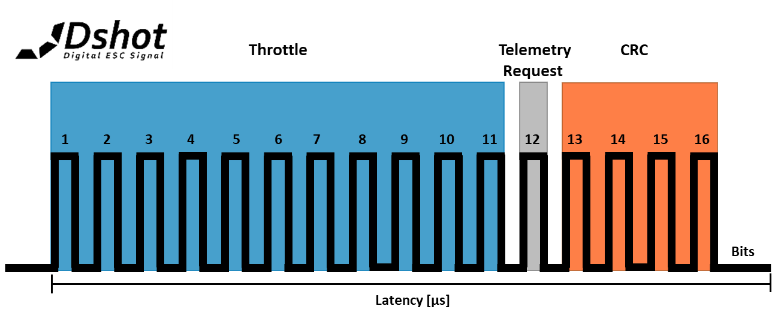

In Dshot, the length of the high time indicates if the transmitted bit is a 0 or a 1. At a data rate of 600 Kbit/s the One High Time (T1H) is 1.25 µs and the Zero High Time (T0H) is 0.625 µs:

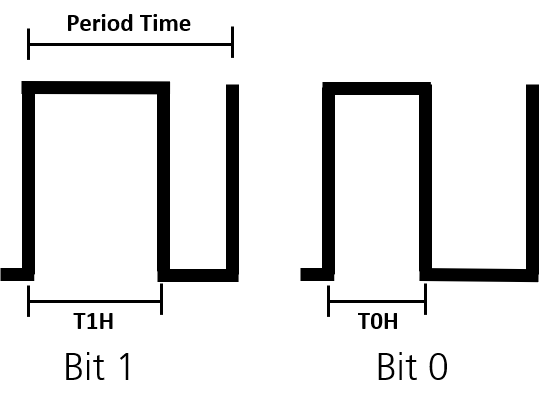

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the Simulink scopes in the model to verify that the loopback is wired correctly. 

- Rx data: 11-bit counter transmitted with the Dshot Tx block

- Valid: Indicating that the data is valid

- Telemetry: The Telemetry bit is set to one when the received data is between 1 - 47 

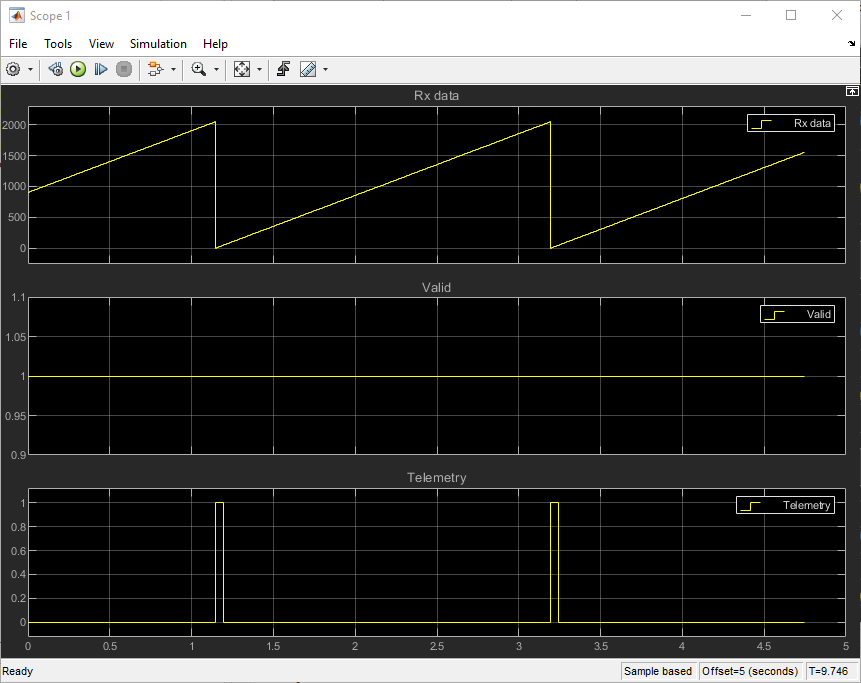

## Additional References

- [Dshot documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_dshot)